%PIECE WISE CONSTANT TREND IDENTIFICATION - ca sa 
data = load("product_5.mat");

id = struct("t",data.time(1:79),"y",data.y(1:79));
val = struct("t",data.time(80:99),"y",data.y(80:99));

m = 2;
P = 12; % default period

f = zeros(length(id.y),2+2*m);
for line = 1:length(id.t) 
    for i = 1:m
        f(line,1) = 1;
        f(line,2) = id.t(line);
        for regressor = 3:2:(2+2*m)
            f(line,regressor) = cos(2*pi*line/P);
            f(line,regressor + 1) = sin(2*pi*line/P);
        end
    end
end

phi = [];
for line = 1:length(id.y)
    phi = [phi; f(line,:)];
end

y = id.y;
theta = phi\y;

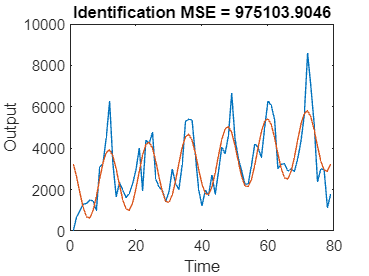


y_hat = phi*theta;
mse = 1/length(id.y)*sum((y_hat-y).^2);

plot(id.t,id.y,id.t,y_hat); title("Identification MSE = " + string(mse));
xlabel("Time"); ylabel("Output");

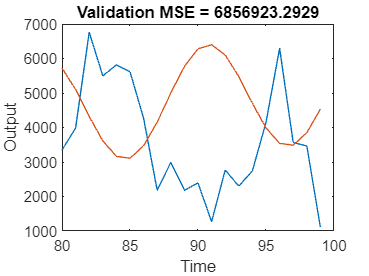


%validation data
f = zeros(length(val.y),2+2*m);
for line = 1:length(val.t) 
    for i = 1:m
        f(line,1) = 1;
        f(line,2) = val.t(line);
        for regressor = 3:2:(2+2*m)
            f(line,regressor) = cos(2*pi*line/P);
            f(line,regressor + 1) = sin(2*pi*line/P);
        end
    end
end

phi = [];
for line = 1:length(val.y)
    phi = [phi; f(line,:)];
end

y = val.y;

y_hat = phi*theta;
mse = 1/length(val.y)*sum((y_hat-y).^2);

plot(val.t,val.y,val.t,y_hat); title("Validation MSE = " + string(mse));
xlabel("Time"); ylabel("Output");